# Two-link planar arm Dynamics 

## Objective:

 Derive  then simulate the equations of motions for a two-link planar using Largrange's method.

## **prerequisite:**

- Symbolic math Understanding ( refer to tutorials in folder   ../../0_Basics/0 - symolic-numeric math)

- Added to path "library" folder

- Manipulator kinematics (content within ../../0-`kinematics` directory)

- Lagrangian formulation concept

- Reference reading: Chapter 7 of Robotics Modelling, Planning and Control  by Bruno Siciliano, Lorenzo Sciavicco, Luigi Villani, and Giuseppe Oriolo  

## background:

- Two-link planar, also called double compound pendulum, moves in 2D only. 

- In this document, the arm is assumed to move in X-Y plane and joints to revolve about Z-axis.

- Gravity is assumed to work in Y-axis

- Links are assumed to be thin bricks with dimentions ($L_x \times L_y \times L_z$) where $L_x$ is the longest side.  

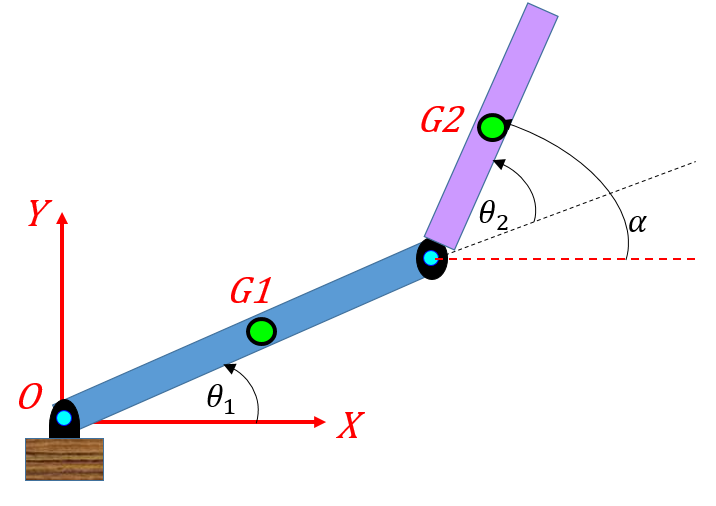              

## Model parameters

syms g % gravity value, (9.81 m/s^2)
syms t % time
syms m1 m2  % masses
syms L_1x L_1y L_1z                        % lengths for LINK #1
syms L_2x L_2y L_2z                        % lengths for LINK #2
syms b1  b2 % viscous damping
syms theta1(t)  q1  q1_D q1_DD % joint 1 angle/velocity/acceleration theta1(t)=q1(t)
syms theta2(t)  q2  q2_D q2_DD % joint 2 angle/velocity/acceleration theta2(t)=q2(t)
syms tau1 tau2 % motor torques

$$I1 = \left(\begin{array}{ccc} \frac{m_{1}\,\left({L_{\mathrm{1y}}}^{2}+{L_{\mathrm{1z}}}^{2}\right)}{12} & 0 & 0\\ 0 & \frac{m_{1}\,\left({L_{\mathrm{1x}}}^{2}+{L_{\mathrm{1z}}}^{2}\right)}{12} & 0\\ 0 & 0 & \frac{m_{1}\,\left({L_{\mathrm{1x}}}^{2}+{L_{\mathrm{1y}}}^{2}\right)}{12} \end{array}\right)$$

$$I2 = \left(\begin{array}{ccc} \frac{m_{2}\,\left({L_{\mathrm{2y}}}^{2}+{L_{\mathrm{2z}}}^{2}\right)}{12} & 0 & 0\\ 0 & \frac{m_{2}\,\left({L_{\mathrm{2x}}}^{2}+{L_{\mathrm{2z}}}^{2}\right)}{12} & 0\\ 0 & 0 & \frac{m_{2}\,\left({L_{\mathrm{2x}}}^{2}+{L_{\mathrm{2y}}}^{2}\right)}{12} \end{array}\right)$$

### Position of center of mass: ${\mathit{\mathbf{p}}}_{\textrm{ci}} ={\left\lbrack x_{\textrm{ci}} \;y_{\textrm{ci}} \;z_{\textrm{ci}} \right\rbrack }^T$ 

X_c1   = (L_1x/2)*cos(theta1(t));
Y_c1   = (L_1x/2)*sin(theta1(t));

alpha  = theta1(t) + theta2(t);
X_c2   = L_1x*cos(theta1(t)) + (L_2x/2)*cos(alpha);
Y_c2   = L_1x*sin(theta1(t)) + (L_2x/2)*sin(alpha);

% put them in position vector [x,y,z]'
p_1   = sym([X_c1; Y_c1; 0]);

$$KE(t) = \begin{array}{l} \frac{m_{2}\,{\left(\frac{L_{\mathrm{2x}}\,\cos\left(\sigma_{3}\right)\,\sigma_{2}}{2}+L_{\mathrm{1x}}\,\cos\left(\theta_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}\theta_{1}\left(t\right)\right)}^{2}}{2}+\frac{m_{2}\,{\left(\frac{L_{\mathrm{2x}}\,\sin\left(\sigma_{3}\right)\,\sigma_{2}}{2}+L_{\mathrm{1x}}\,\sin\left(\theta_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}\theta_{1}\left(t\right)\right)}^{2}}{2}+\frac{m_{1}\,\left({L_{\mathrm{1x}}}^{2}+{L_{\mathrm{1y}}}^{2}\right)\,\sigma_{1}}{24}+\frac{m_{2}\,\left({L_{\mathrm{2x}}}^{2}+{L_{\mathrm{2y}}}^{2}\right)\,{\left(\frac{\partial }{\partial t}\theta_{2}\left(t\right)\right)}^{2}}{24}+\frac{{L_{\mathrm{1x}}}^{2}\,m_{1}\,{\cos\left(\theta_{1}\left(t\right)\right)}^{2}\,\sigma_{1}}{8}+\frac{{L_{\mathrm{1x}}}^{2}\,m_{1}\,{\sin\left(\theta_{1}\left(t\right)\right)}^{2}\,\sigma_{1}}{8}\\ \mathrm{where}\\ \sigma_{1}={\left(\frac{\partial }{\partial t}\theta_{1}\left(t\right)\right)}^{2}\\ \sigma_{2}=\frac{\partial }{\partial t}\theta_{1}\left(t\right)+\frac{\partial }{\partial t}\theta_{2}\left(t\right)\\ \sigma_{3}=\theta_{1}\left(t\right)+\theta_{2}\left(t\right) \end{array}$$

p_2   = sym([X_c2; Y_c2; 0]);   

### Link CoM velocities and accelerations:  $V_{\textrm{ci}} ={\left\lbrack \dot{x_{\textrm{ci}} } \;\dot{y_{\textrm{ci}} } \;\dot{z_{\textrm{ci}} } \right\rbrack }^T$, $a_{\textrm{ci}} ={\left\lbrack \ddot{\;x_{\textrm{ci}} } \;\ddot{\;y_{\textrm{ci}} } \ddot{\;z_{\textrm{ci}} } \right\rbrack }^T$ 

V_c1 = diff( p_1, t);  
V_c2 = diff( p_2, t); 

a_c1      = diff(p_1, t, 2);
a_c2     = diff(p_2, t, 2); 

### Rotational velocity: $\omega_{\textrm{ci}} ={\left\lbrack \omega_x \;\omega_y \;\omega_z \right\rbrack }^T$

Rotations only happen around Z-axis for each link joint

omega_1   = [0; 0; diff(theta1, t)];
omega_2   = [0; 0; diff(theta2, t)];

### Inertia about center of mass:

 Each link is assumed a rectangular prism. Inertia for this fundamental shape can be computed about a local body frame positioned at center of mass (CoM).

define some formulas for the inertias of these fundamental shapes:

I_brick = @(Lx,Ly,Lz,m)...

$$ans = \left(\begin{array}{cccccccc} t & L_{\mathrm{1x}} & L_{\mathrm{1y}} & L_{\mathrm{2x}} & L_{\mathrm{2y}} & g & m_{1} & m_{2} \end{array}\right)$$

    ( [m*(Ly^2 + Lz^2)/12,          0         ,            0        ; ...
              0          ,  m*(Lx^2 + Lz^2)/12,            0        ; ...
              0          ,          0         ,   m*(Lx^2 + Ly^2)/12;] );

Calculate the inertia matrix for each link:

I1 = I_brick(L_1x, L_1y, L_1z , m1)
I2 = I_brick(L_2x, L_2y, L_2z , m2)

## Euler-Lagrange method

$\frac{d}{dt}\frac{\partial L}{\partial \dot{q}_k} - \frac{\partial L}{\partial q_k} = Q_k $     for     $k=1,2, \dots, n$

where  *n* is the DOF of the system, {$q_1, q_2, \dots, q_n$} is a set of generalized coordinates, {$Q_1, Q_2, \dots, Q_n$} is the set of generalized forces associated with those coordinates, and the Lagrangian:  

***L***** =  *****T***  ***-***  ***V****,* is defined as the difference between the kinetic and potential energy of the  *n-* DOF system.

### Generalized coordinates

choose *q = {*$\theta_1 \thinspace, \theta_2$*}* 

This is a 2 degree of freedom system, we will derive two 2nd order ODEs.

### Define the system kinetic energy

Use previously derived expressions for body velocities to define the "system" Kinetic Energy.  

Since we've attached our body frames to the **centre of masses** of every link, the kinetic energy for the $i^{\textrm{th}}$ link can be stated as:


$${\textrm{KE}}_i =\;\frac{1}{2}v_{c_i }^T {\ldotp m}_i {\;\ldotp v}_{c_i } \;+\;\frac{1}{2}\ldotp \omega_{B_i }^T \ldotp \left\lbrack I_{c_i } \right\rbrack \ldotp \omega_{B_i }$$


The total system kinetic energy is then just the sum of the "*N*" individual link kinetic energies, ie:


$${\textrm{KE}}_{\textrm{system}} =\;\sum_{i=1}^N {\textrm{KE}}_i$$


***Translational*** kinetic energy is:

K_t1 = 0.5*m1*(V_c1.') *  V_c1;
K_t2 = 0.5*m2*(V_c2.') *  V_c2;
KE_trans = K_t1 + K_t2;

**Rotational** kinetic energy is:

KE_rot1 = 0.5 * (omega_1.') * I1 *  omega_1;

#######################################################
### q = theta1(t)
### 
### LHS of EOM is: 
### 
        (L_1x^2*m1*diff(theta1(t), t, t))/3 + L_1x^2*m2*diff(theta1(t), t, t) + (L_1y^2*m1*diff(theta1(t), t, t))/12 + (L_2x^2*m2*diff(theta1(t), t, t))/4 + (L_2x^2*m2*diff(theta2(t), t, t))/4 + (L_2x*g*m2*cos(theta1(t) + theta2(t)))/2 + (L_1x*g*m1*cos(theta1(t)))/2 + L_1x*g*m2*cos(theta1(t)) - (L_1x*L_2x*m2*sin(theta2(t))*diff(theta2(t), t)^2)/2 + L_1x*L_2x*m2*cos(theta2(t))*diff(theta1(t), t, t) + (L_1x*L_2x*m2*cos(theta2(t))*diff(theta2(t), t, t))/2 - L_1x*L_2x*m2*sin(theta2(t))*diff(theta1(t), t)*diff(theta2(t), t)
### 
### RHS of EOM is: 
        Q1_s
#######################################################
### q = theta2(t)
### 
### LHS of EOM is: 
### 
        (L_2x^2*m2*diff(theta1(t), t, t))/4 + (L_2x^2*m2*diff(theta2(t), t, t))/3 + (L_2y^2*m2*diff(theta2(t), t, t))/12 + (L_2x*g*m2*cos(theta1(t) + theta2(t)))/2 + (L_1x*L_2x*m2*sin(theta2(t))*diff(theta1(t), t)^2)/2 + (L_1x*L_

KE_rot2 = 0.5 * (omega_2.') * I2 *  omega_2;
KE_rot   = KE_rot1  + KE_rot2;   

$$ans = \begin{array}{l} \frac{{L_{\mathrm{1x}}}^{2}\,m_{1}\,\sigma_{1}}{3}+{L_{\mathrm{1x}}}^{2}\,m_{2}\,\sigma_{1}+\frac{{L_{\mathrm{1y}}}^{2}\,m_{1}\,\sigma_{1}}{12}+\frac{{L_{\mathrm{2x}}}^{2}\,m_{2}\,\sigma_{1}}{4}+\frac{{L_{\mathrm{2x}}}^{2}\,m_{2}\,\sigma_{2}}{4}+\frac{L_{\mathrm{2x}}\,g\,m_{2}\,\cos\left(\theta_{1}\left(t\right)+\theta_{2}\left(t\right)\right)}{2}+\frac{L_{\mathrm{1x}}\,g\,m_{1}\,\cos\left(\theta_{1}\left(t\right)\right)}{2}+L_{\mathrm{1x}}\,g\,m_{2}\,\cos\left(\theta_{1}\left(t\right)\right)-\frac{L_{\mathrm{1x}}\,L_{\mathrm{2x}}\,m_{2}\,\sin\left(\theta_{2}\left(t\right)\right)\,{\left(\frac{\partial }{\partial t}\theta_{2}\left(t\right)\right)}^{2}}{2}+L_{\mathrm{1x}}\,L_{\mathrm{2x}}\,m_{2}\,\cos\left(\theta_{2}\left(t\right)\right)\,\sigma_{1}+\frac{L_{\mathrm{1x}}\,L_{\mathrm{2x}}\,m_{2}\,\cos\left(\theta_{2}\left(t\right)\right)\,\sigma_{2}}{2}-L_{\mathrm{1x}}\,L_{\mathrm{2x}}\,m_{2}\,\sin\left(\theta_{2}\left(t\right)\right)\,\frac{\partial }{\partial t}\theta_{2}\left(t\right)\,\frac{\partial }{\partial t}\theta_{1}\left(t\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{\partial^{2}}{\partial t^{2}}\theta_{1}\left(t\right)\\ \sigma_{2}=\frac{\partial^{2}}{\partial t^{2}}\theta_{2}\left(t\right) \end{array}$$

So our total kinetic energy is:

KE = KE_trans + KE_rot

### Define the system potential energy:

Potential energy is with respect to the datum in Y-axis (where gravity is defined):

PE1 = g*m1*p_1(2);
PE2 = g*m2*p_2(2);

PE = PE1 + PE2;

### Define the system Lagrangian:

L_var = KE - PE;

Note the symbolic variables that are inside the Lagrangian:

symvar(L_var)

Now all we need to do is a series of derivative calculations according to Lagrange's equation:

 
$$\frac{d}{dt}\frac{\partial L}{\partial \dot{q}_k} - \frac{\partial L}{\partial q_k} = Q_k $$
                
$$k=1,2, \dots, n$$


Where:

- *L = KE - PE, *is our system lagrangian

- *q = *$\left\lbrace \theta_1 ,\theta_2 \right\rbrace$ are the generalised co-ordinates for our 4-dof manipulator

- $Q_k$ are the generalised forces (Torques) for our system

## Apply Lagrange's equation:

First, create some variables that define our generalised co-ordinates.  Using 2 sets of these generalised co-ordinates:

- the **ACTUAL** set of symbols are our "proper" time-dependent set of symbols

- the **HOLDER** set are for easier expression manipulation (these are purely for convenience)

actual_vars_list = formula( [ theta1,  theta2]);
holder_vars_list =          [     q1,      q2];

Create a Lagrangian object using the class <`bh_lagr4manips_CLS`>

lag_obj = bh_lagr4manips_CLS( KE, PE, actual_vars_list, holder_vars_list);

Compute the system's equations of motion:

lag_obj = lag_obj.calc_eom();

So what do the equations of motion actually look like ?

lag_obj.show_eom()

#######################################################
### q = q1
### 
### Qk (HOLDER) is: 
### 
      tau1 - b1*q1_D
#######################################################
### q = q2
### 
### Qk (HOLDER) is: 
### 
      tau2 - b2*q2_D

If you want to look at an individual equation of motion (eg: the LHS of the $\theta_1$ equation), then you could do this:

lag_obj.get_eom(1, 'actual', 'LHS')

$$the\_Qk\_vec = \left(\begin{array}{c} \tau_{1}-b_{1}\,q_{1,D}\\ \tau_{2}-b_{2}\,q_{2,D} \end{array}\right)$$

In a moment we'll show how to "collect" the terms in these EOMs and present them in a format that looks like this:

- 
$$M(q).\ddot{q} \enspace + \enspace
C(q,\dot{q}).\dot{q} \enspace + \enspace
K(q).q \enspace + \enspace
 g(q) = Q$$


## **Define the Generalised forces:**

Recall the formula for the generalised forces acting on the system:


$$Q_k = 
\sum_{i=1}^{Nf_{nc}}
\pmatrix{
\vec{F_i} \thinspace . \thinspace \frac{\partial \vec{v \thinspace _i}}{\partial \dot{q \thinspace}_k}
}  \enspace + \enspace
\sum_{j=1}^{N\tau_{nc}}
\pmatrix{
\vec {\tau_j} \thinspace . \thinspace \frac{\partial \vec{\omega \thinspace _j}}{\partial \dot{q \thinspace}_k}
}
$$


where:

- $Q_k$     :    is the generalised force associated with the $k^{th}$ generalised co-ordinate $q_k$

- $Nf_{nc}$ :    is the number of active NON conservative forces

- $N\tau_{nc}$:    is the number of active NON conservative TORQUES

- $\vec{v_i}$    :    is the velocity vector of the point associated with the applied force.

- $\vec{\omega_i}$   :    is the angular velocity about the point associated with the applied torque. 

For each link, define a matrix, whos columns represent the vectors of the non-conservative torques acting on that body, and another matrix whose columns represent the angular velocities associated with these torques.

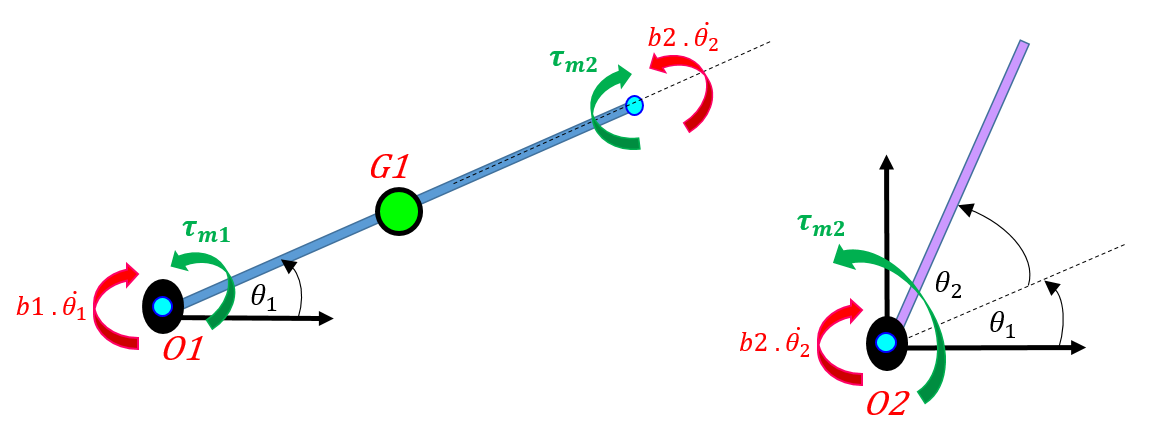

For **LINK #1**:

tau_mat_1 = [ ...
               0,                0,                 0,                  0;          
               0,                0,                 0,                  0;  

$$ans = \left(\begin{array}{c} \tau_{1}-b_{1}\,q_{1,D}\\ \tau_{2}-b_{2}\,q_{2,D} \end{array}\right)$$

          (tau1),     (-b1*diff(theta1, t)),  (-tau2),         (b2*diff(theta2, t));  ]; 
       
omega_mat_1 = [ omega_1,    omega_1,   omega_1,    omega_1 ];

For **LINK #2**:

tau_mat_2 = [ ...
               0,                         0;         
               0,                         0;

res_T =   bh_MCKGQ_CLS with properties:

           M: [2×2 sym]
           C: [2×2 sym]
           K: [2×2 sym]
           G: [2×1 sym]
           Q: [2×1 sym]
     ACC_col: [2×1 sym]
     VEL_col: [2×1 sym]
     POS_col: [2×1 sym]
    acc_eoms: [2×1 sym]


          (tau2),     (-b2*diff(theta2, t));  ];        
   
omega_mat_2 = [ omega_1+omega_2,    omega_1+omega_2];

 Concatenate these into single matrices:

tau_mat_actual = [tau_mat_1, tau_mat_2];

$$ans = \left(\begin{array}{cc} \frac{{L_{\mathrm{1x}}}^{2}\,m_{1}}{3}+{L_{\mathrm{1x}}}^{2}\,m_{2}+\frac{{L_{\mathrm{1y}}}^{2}\,m_{1}}{12}+\frac{{L_{\mathrm{2x}}}^{2}\,m_{2}}{4}+L_{\mathrm{1x}}\,L_{\mathrm{2x}}\,m_{2}\,\cos\left(q_{2}\right) & \frac{L_{\mathrm{2x}}\,m_{2}\,\left(L_{\mathrm{2x}}+2\,L_{\mathrm{1x}}\,\cos\left(q_{2}\right)\right)}{4}\\ \frac{L_{\mathrm{2x}}\,m_{2}\,\left(L_{\mathrm{2x}}+2\,L_{\mathrm{1x}}\,\cos\left(q_{2}\right)\right)}{4} & \frac{m_{2}\,\left(4\,{L_{\mathrm{2x}}}^{2}+{L_{\mathrm{2y}}}^{2}\right)}{12} \end{array}\right)$$

omega_mat_actual   = [  omega_mat_1,   omega_mat_2];

Now let's compute $Q_k$:

Compute $Q_k$:


$$Q_k = 
\sum_{i=1}^{Nf_{nc}}
\pmatrix{
\vec{F_i} \thinspace . \thinspace \frac{\partial \vec{v \thinspace _i}}{\partial \dot{q \thinspace}_k}
}  \enspace + \enspace
\sum_{j=1}^{N\tau_{nc}}
\pmatrix{
\vec {\tau_j} \thinspace . \thinspace \frac{\partial \vec{\omega \thinspace _j}}{\partial \dot{q \thinspace}_k}
}
$$


To do this we'll create a generalised force object using the class <`bh_genF4manips_CLS`>

genF_obj = bh_genF4manips_CLS( tau_mat_actual, ...
                               omega_mat_actual, ...
                               actual_vars_list, ...

$$ans = \left(\begin{array}{cc} 0 & 0\\ 0 & 0 \end{array}\right)$$

                               holder_vars_list);

And now calculate our system's generalised forces:                          

genF_obj = genF_obj.calc_genF();

$$ans = \left(\begin{array}{c} \frac{g\,\left(L_{\mathrm{2x}}\,m_{2}\,\cos\left(q_{1}+q_{2}\right)+L_{\mathrm{1x}}\,m_{1}\,\cos\left(q_{1}\right)+2\,L_{\mathrm{1x}}\,m_{2}\,\cos\left(q_{1}\right)\right)}{2}\\ \frac{L_{\mathrm{2x}}\,g\,m_{2}\,\cos\left(q_{1}+q_{2}\right)}{2} \end{array}\right)$$

What do the $Q_k's$ look like?

genF_obj.show_genF_holder()

$$ans = \left(\begin{array}{c} \tau_{1}-b_{1}\,q_{1,D}\\ \tau_{2}-b_{2}\,q_{2,D} \end{array}\right)$$

Or we can retrieve all of the $Q_k's$ as a vector:

the_Qk_vec = genF_obj.get_Qk('all', 'holder')

**Note:**

For planar arms, the generalized forces can be easily found as torque minus fricition force $\tau -b\dot{\;\theta \;}$ for each link.

## Absorb the Generalised Forces:

We can now insert these Generalised forces into the "Lagrangian" object that we created earlier, and then recalculate the equations of motion:

lag_obj = lag_obj.calc_eom(genF_obj);

 Now echo our equations:

lag_obj.get_eom( 1:2, 'holder', 'RHS')

$$M\_bar = \left(\begin{array}{cc} \frac{{L_{\mathrm{1x}}}^{2}\,m_{1}}{3}+{L_{\mathrm{1x}}}^{2}\,m_{2}+\frac{{L_{\mathrm{1y}}}^{2}\,m_{1}}{12}+\frac{{L_{\mathrm{2x}}}^{2}\,m_{2}}{4} & 0\\ 0 & \frac{m_{2}\,\left(4\,{L_{\mathrm{2x}}}^{2}+{L_{\mathrm{2y}}}^{2}\right)}{12} \end{array}\right)$$

## get the M,C,K,G,Q matrices:

We can express our system equations of motion in the following form:


$$M(q).\ddot{q} \enspace + \enspace
C(q,\dot{q}).\dot{q} \enspace + \enspace
K(q).q \enspace + \enspace
 g(q) = Q$$


Note: viscous friction is included in the generalized force Q

 lag_obj = lag_obj.create_MCKGQ();

Retrieve the MCKGQ struct:

res_T = lag_obj.get_MCKGQ()

And let's have a look at each of these terms:

Here's **M**:

res_T.M

$$simplified\_model = \left(\begin{array}{c} q_{1,\mathrm{DD}}\,\left(\frac{{L_{\mathrm{1x}}}^{2}\,m_{1}}{3}+{L_{\mathrm{1x}}}^{2}\,m_{2}+\frac{{L_{\mathrm{1y}}}^{2}\,m_{1}}{12}+\frac{{L_{\mathrm{2x}}}^{2}\,m_{2}}{4}\right)+b_{1}\,q_{1,D}\\ b_{2}\,q_{2,D}+\frac{m_{2}\,q_{2,\mathrm{DD}}\,\left(4\,{L_{\mathrm{2x}}}^{2}+{L_{\mathrm{2y}}}^{2}\right)}{12} \end{array}\right)$$

Here's **C**:

res_T.C

Here's **K**:

res_T.K

Here's **G**:

res_T.G

Here's **Q**:

res_T.Q

## get the decentralized simplified model :

This will be used in decentralized control schemes.

Decompose the inertia matrix into a constant diagonal terms and residual terms


$$M\left(q\right)=\bar{M} +\Delta M\left(q\right)$$
 

The disturbance equation contains the remaining terms besides the inertia residual terms


$$d=\bar{\Delta M\left(q\right)} \ddot{\;q} +C\left(q,\dot{\;q} \right)\dot{\;q} +g\left(q\right)$$


n = length(res_T.M);
M_diag = eye(n).*res_T.M;
% zero out any cos and sin terms
M_bar = subs(M_diag, [ cos(q1),sin(q1), cos(q2) sin(q2)],[0,0,0,0])
M_delta = res_T.M-M_bar;

Friction terms

Fv = [b1,        0;
             0,  b2];

Decentralized simplified model


$$\bar{M} \ddot{\;q} +\textrm{Fv}\dot{\;q} =u$$


simplified_model = M_bar*[q1_DD;q2_DD]+Fv*[q1_D;q2_D]

Disturbance equation

C_terms = res_T.C;
G_terms = res_T.G;
disturbance_terms = M_delta*[q1_DD;q2_DD]+C_terms*[q1_D;q2_D] + G_terms;

#### Simplified State Space model

The simplifed model can be formated in state space format as follows

state vector: $x=\left\lbrack \begin{array}{c}
\mathit{\mathbf{q}}\\
\dot{\;\mathit{\mathbf{q}}} 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
q_1 \\
q_2 \\
\dot{\;q_1 } \\
\dot{\;q_2 } 
\end{array}\right\rbrack$

Taking derivatives


$$\dot{\;x} =\left\lbrack \begin{array}{c}
\dot{\;x_1 } \\
\dot{\;x_2 } 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
x_2 \\
-M^{-1} \left(F_v x_2 \right)+M^{-1} u
\end{array}\right\rbrack$$


State equations:


$$\begin{array}{l}
\dot{\mathit{\mathbf{x}}} =\textrm{Ax}+\textrm{Bu}\\
\mathit{\mathbf{y}}=\textrm{Cx}+\textrm{Du}
\end{array}$$



$${\mathit{\mathbf{A}}}_{4\times 4} =\left\lbrack \begin{array}{cc}
O_{2\times 2}  & I_{2\times 2} \\
O_{2\times 2}  & -M^{-1} \textrm{Fv}
\end{array}\right\rbrack$$



$${\mathit{\mathbf{B}}}_{4\times 2} =\left\lbrack \begin{array}{c}
O_{2\times 2} \\
M^{-1} 
\end{array}\right\rbrack$$



$${\mathit{\mathbf{C}}}_{4\times 4} =\left\lbrack \begin{array}{cc}
I_{2\times 2}  & O_{2\times 2} \\
O_{2\times 2}  & I_{2\times 2} 
\end{array}\right\rbrack$$



$$D=\left\lbrack O_{4\times 2} \right\rbrack$$


n = 2;
A = [ zeros(n),           eye(n);
      zeros(n),   -inv(M_bar)*Fv;
    ];
B = [ zeros(n);
      inv(M_bar)
    ];
C = [   eye(n),  ones(n);
      zeros(n),   eye(n);
    ];
D = zeros(2*n,n);


Create matlab function for the state space equations

matlabFunction(A,B,C,D,'File','gen_twolink_ss','Optimize',false);

## create the MATLAB function blocks for Simulink:

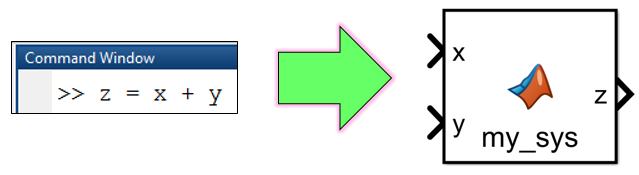

To use/solve these derived equations of motion we'll create a MATLAB Function block that can be used inside Simulink:

lag_obj.create_MLF_blocks()

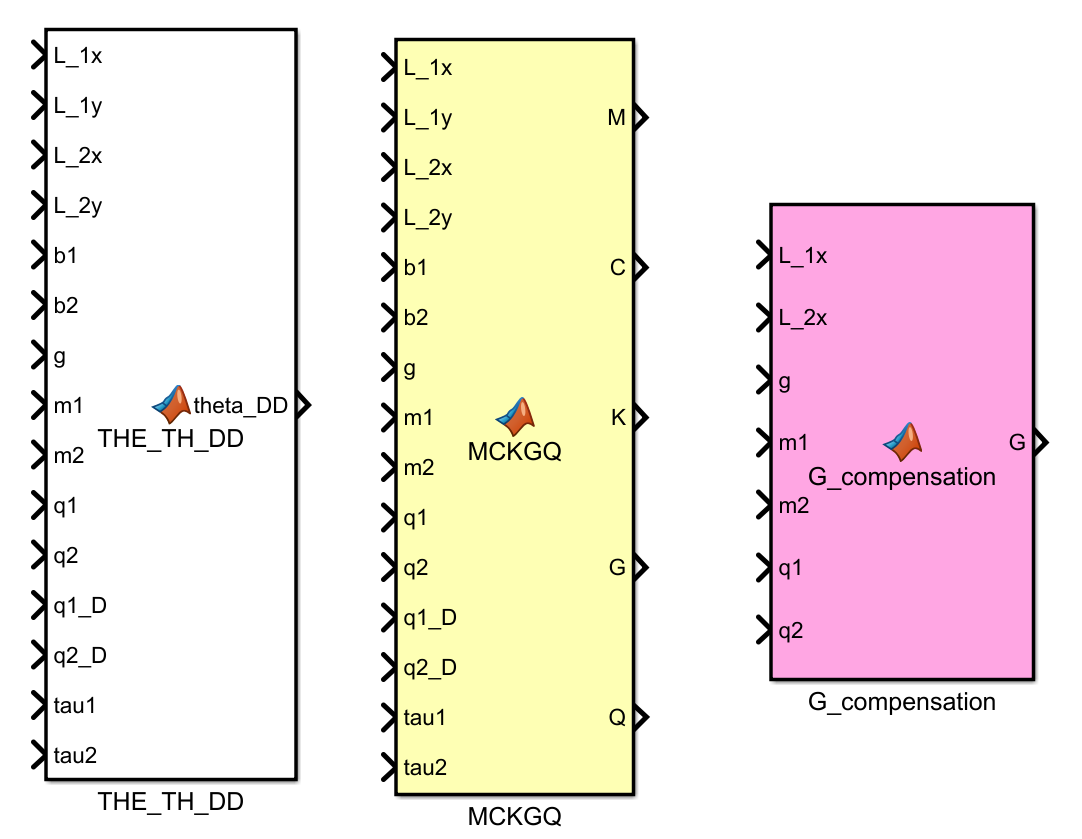

The "MCKGQ" block can then be pasted into a Simulink model for a simulation of the robot.  

### decentralized model blocks

Create indivisual terms for decentralized control. These blocks will be used in simulink for arm control.

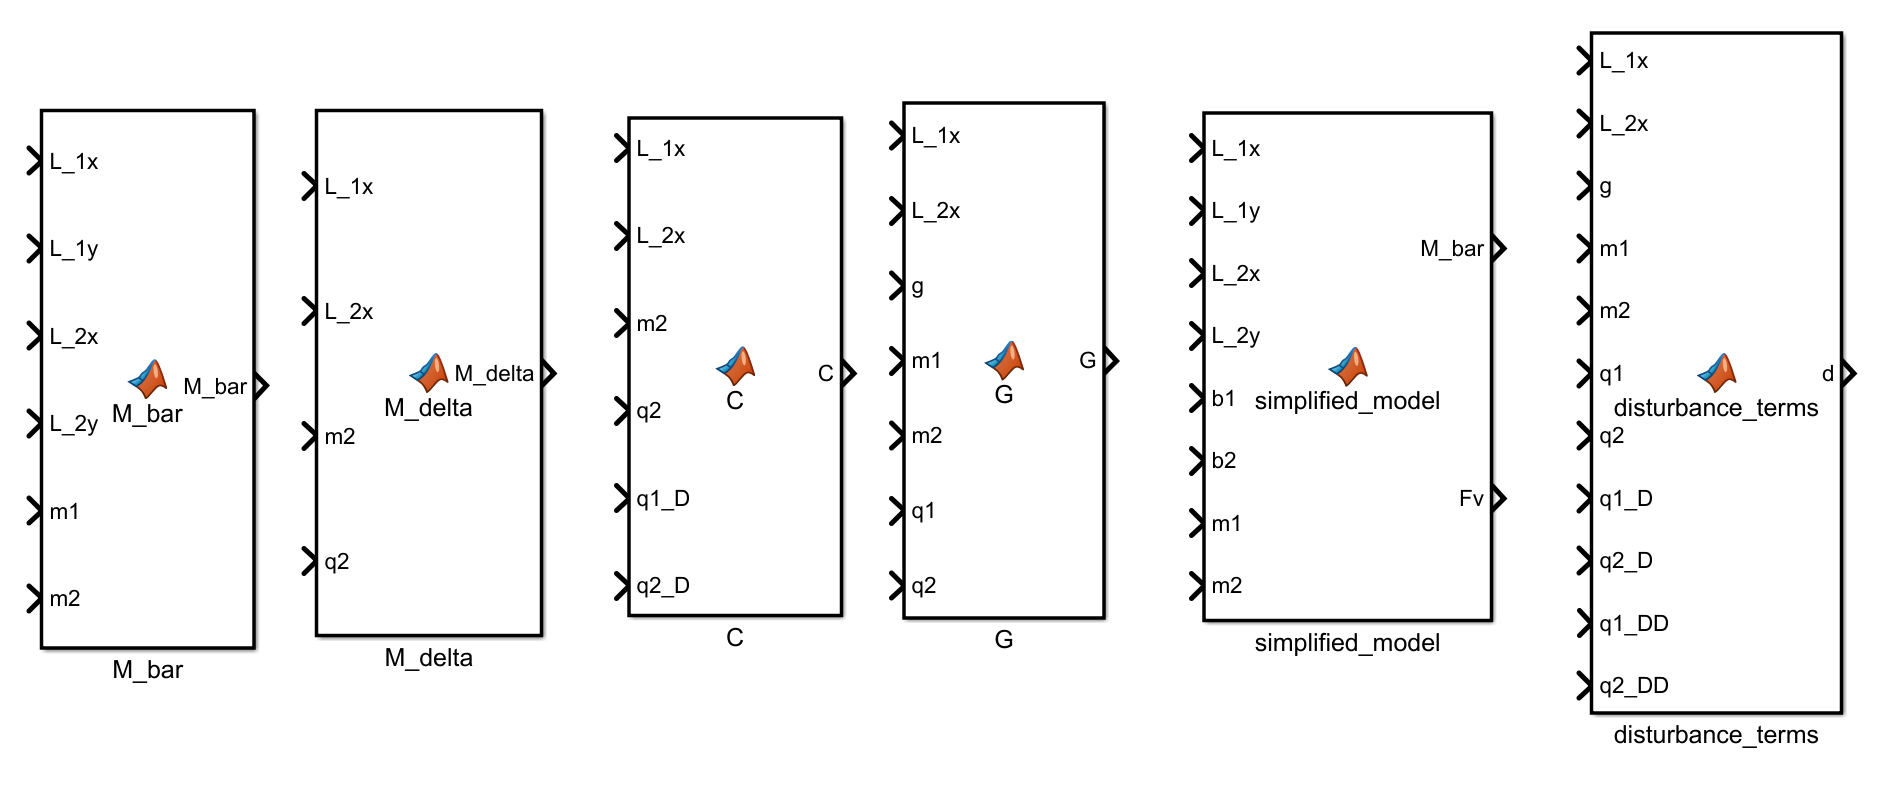

MODEL_NAME = 'tmp_models_for_simple_twolink';
if(4==exist(MODEL_NAME))
    close_system(MODEL_NAME, 0);
    delete(MODEL_NAME);
end
new_system(MODEL_NAME)
open_system(MODEL_NAME) 
            
% the decntralized terms M_bar and d                 
matlabFunctionBlock( [MODEL_NAME,'/M_bar'], ... 
                     M_bar, ...                         
                     'Optimize', false, ...
                     'Outputs', {'M_bar'}   );     

matlabFunctionBlock( [MODEL_NAME,'/M_delta'], ... 
                     M_delta, ...                         
                     'Optimize', false, ...
                     'Outputs', {'M_delta'}   );
matlabFunctionBlock( [MODEL_NAME,'/C'], ... 
                     C_terms, ...                         
                     'Optimize', false, ...
                     'Outputs', {'C'}   );
matlabFunctionBlock( [MODEL_NAME,'/G'], ... 
                     G_terms, ...                         
                     'Optimize', false, ...
                     'Outputs', {'G'}   );
matlabFunctionBlock( [MODEL_NAME,'/disturbance_terms'], ... 
                     disturbance_terms, ...                         
                     'Optimize', false, ...
                     'Outputs', {'d'}   ); 

Error using run (line 66)
sim_params.m not found.


matlabFunctionBlock( [MODEL_NAME,'/simplified_model'], ... 
                     M_bar,Fv, ...                         
                     'Optimize', false, ...
                     'Outputs', {'M_bar','Fv'}   ); 

### Defining parameters:

Before running the Simulink model, run tthe script to load parameters (eg: inertias, initial conditions, etc) into the MATLAB workspace.  In addition to implementing our hand derived equations of motion, we have also created a Simscape Multibody of the same 2 link manipulator.  We compare the results of our hand derivation to the Simscape model.

run('sim_params.m')

### Openning Simulink Model

open_system('sim_1_twolink_planar_model');

# References

[Teaching Rigid Body Dynamics – a combination of symbolic and numeric computing Video - MATLAB (mathworks.com)](https://www.mathworks.com/videos/teaching-rigid-body-dynamics-a-combination-of-symbolic-and-numeric-computing-1506004876316.html?s_tid=srchtitle_Teaching%20Rigid%20Body%20Dynamics_1)

`Bradley Horton : 01-Aug-2016, bradley.horton@mathworks.com.au`